modelName = 'TA2445';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')

SetPointValues = logspace(-1,1,20);
spv_length = length(SetPointValues);
k = 1;
for i = 1:1:spv_length
    for j = 1:1:spv_length
        in(k) = Simulink.SimulationInput(modelName);
        in(k) = in(k).setBlockParameter(modelName + "/k1_Gain",...
            'Gain',num2str(SetPointValues(i)));
        in(k) = in(k).setBlockParameter(modelName + "/k2_Gain",...
            'Gain',num2str(SetPointValues(j)));
        k = k + 1;
    end
end

out_TA2445 = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[19-Feb-2023 22:43:32] シミュレーションの実行中...
[19-Feb-2023 22:43:34] シミュレーション実行 1/400 が完了
[19-Feb-2023 22:43:35] シミュレーション実行 2/400 が完了
[19-Feb-2023 22:43:36] シミュレーション実行 3/400 が完了
[19-Feb-2023 22:43:37] シミュレーション実行 4/400 が完了
[19-Feb-2023 22:43:38] シミュレーション実行 5/400 が完了
[19-Feb-2023 22:43:39] シミュレーション実行 6/400 が完了
[19-Feb-2023 22:43:39] シミュレーション実行 7/400 が完了
[19-Feb-2023 22:43:40] シミュレーション実行 8/400 が完了
[19-Feb-2023 22:43:40] シミュレーション実行 9/400 が完了
[19-Feb-2023 22:43:41] シミュレーション実行 10/400 が完了
[19-Feb-2023 22:43:42] シミュレーション実行 11/400 が完了
[19-Feb-2023 22:43:42] シミュレーション実行 12/400 が完了
[19-Feb-2023 22:43:43] シミュレーション実行 13/400 が完了
[19-Feb-2023 22:43:43] シミュレーション実行 14/400 が完了
[19-Feb-2023 22:43:44] シミュレーション実行 15/400 が完了
[19-Feb-2023 22:43:45] シミュレーション実行 16/400 が完了
[19-Feb-2023 22:43:45] シミュレーション実行 17/400 が完了
[19-Feb-2023 22:43:46] シミュレーション実行 18/400 が完了
[19-Feb-2023 22:43:46] シミュレーション実行 19/400 が完了
[19-Feb-2023 22:43:47] シミュレーション実行 20/400 が完了
[19-Feb-2023 22:43:48] シミュレーション実行 21/400 が完了
[19-Feb-2023 22:43:49] シミ

out_TA2445 = 1x400 Simulink.SimulationOutput 配列



Bfinal_TA2445 = zeros(spv_length^2,1);
for simIdx = 1:spv_length^2
    Bfinal_TA2445(simIdx,1) = out_TA2445(simIdx).yout{1}.Values.Data(end);
end

Bfinal_TA2445 = reshape(Bfinal_TA2445,[spv_length,spv_length]);
[X,Y] = meshgrid(logspace(-1,1,spv_length),logspace(-1,1,spv_length));

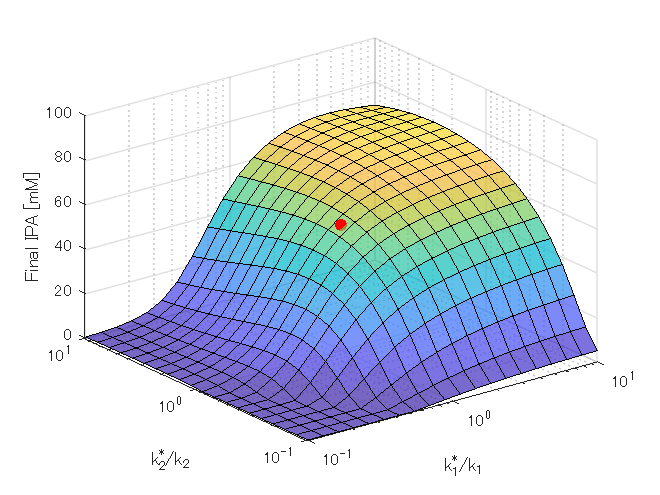

figure('Position', [100 100 480 360]);
surf(X,Y,Bfinal_TA2445);
xlim([0.1 10])
ylim([0.1 10])
zlim([0 100])
xlabel('k_1^*/k_1')
ylabel('k_2^*/k_2')
zlabel('Final IPA [mM]')
set(gca,'xscale','log','yscale','log')
alpha(0.7)
clim([0 80])
hold on
plot3(1,1,maxIPA_TA2445,'ro','MarkerFaceColor','red')
hold off